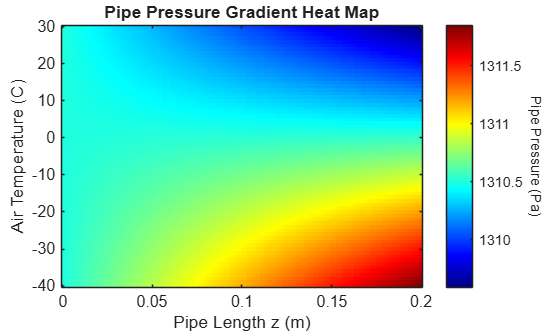

clear
clc

% System Properties
T_air = -40:1:30; % air temperature (C)
flow_rate = 1; % flow rate of pump (liter/min)
m_dot = flow_rate/60; % mass flow rate (kg/s)

D = 0.00555; % diameter (m)
r = D/2; % radius (m)
L = 0.2; % length (m)
cp_water = 4186; % specific heat capacity (J/kg*K)
h = 15; % heat transfer coefficient (W/m^2K)
rho = 1000; % density (kg/m^3)

A = pi*r^2; % cross sectional area (m^2)
u = m_dot/(rho*A); % average velocity (m/s)
P = pi*D; % perimeter (m)

z = linspace(0, L, 100);  % pipe length (m);
T_in = 1.67; % water temperature (C)

dPdz_map = zeros(length(T_air), length(z));
sigma_map = zeros(size(dPdz_map));

for j = 1:length(T_air)
    T = zeros(size(z));
    T(1) = T_in;
    % temperature along pipe
    for i = 2:length(z)
        dz = z(i)-z(i-1); % change in length
        dTdz = -(h*P/(m_dot*cp_water))*(T(i-1)-T_air(j)); % change in temperature across z
        T(i) = T(i-1)+dTdz*dz; % temperature across pipe
    end
    mu = 0.001*exp(-0.033*(T-20)); %Pa*s 
    dPdz = (32*mu*u)/(D^2); % change in pressure across z
    dPdz_map(j,:) = dPdz; % heat map

    Pz = cumtrapz(z, dPdz); % pressure along pipe
end


figure;
imagesc(z, T_air, dPdz_map)
set(gca,'YDir','normal')
xlabel('Pipe Length z (m)')
ylabel('Air Temperature (C)')
title('Pipe Pressure Gradient Heat Map')
colormap(jet);
cb = colorbar(); 
ylabel(cb, 'Pipe Pressure (Pa)', 'Rotation', 270)
hold off;

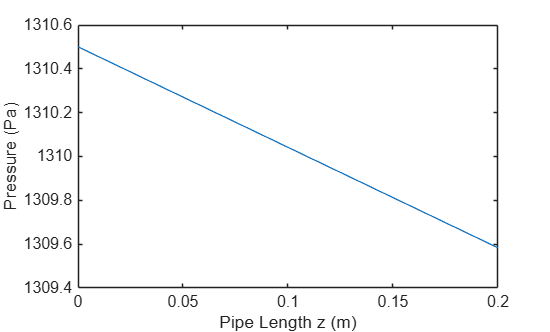


figure;
plot(z, dPdz);
xlabel('Pipe Length z (m)');
ylabel('Pressure (Pa)');

clear
clc
% System Properties
T_air = -15; % air temperature (C) 
T = 1.67; % water initial temperature (C)
T_freeze = 0; % temperature for freezing (C)
T_nucleation = -5; % temperature for nucleation (C)

cp_water = 4186; % specific heat capacity water (J/kg*K)
cp_ice = 2100; % specific heat capacity ice (J/kg*K)
L_f = 334000; % latent heat of fusion (J/kg)

D = 0.00555; % m
r = D/2; % m
L = 0.2; % m
A = D*pi*L; % convection area (m^2)
V = pi*r^2*L; % volume of water (m^3)

rho = 1000; % density (kg/m^3)
m = rho*V; % mass (kg)

dt = 1; % time step (s)
t_max = 60*60*2;

h = 15; % heat transfer coefficient (W/m^2*K)
t_wall = 0.00028; % pipe wall thickness (m)
sigma_fail = 4e7; % copper pipe failure stress (Pa)
K = 2.2e9; % bulk modulus of water (Pa)
latent_remaining = m*L_f; % J
frozen = 0;

phase = "liquid";
burst = false;
T_hist = zeros(1, t_max);

for i = 1:t_max

    % when temperature goes below nucleation temperature it changes from
    % liquid to freezing
    if phase == "liquid" && T <= T_nucleation
        phase = "freezing";
    end
    
    % when phase is liquid
    if phase =="liquid"
        T = T-h*A/(m*cp_water)*(T-T_air)*dt;
    
    % when water is freezing
    elseif phase == "freezing"

        Q = h*A*(T-T_air)*dt; % freezing water creates heat
        dQ = min(Q, latent_remaining);
        
        % heat remaining after being absorbed by pipe
        latent_remaining = latent_remaining-dQ;
        frozen = 1-latent_remaining/(m*L_f);

        % pressure from expansion
        strain = 0.09*frozen; % calculate strain from 9% expansion
        P = K*strain; % calculate pressure from strain
        sigma = P*r/t_wall; % calculate hoop stress from pressure
        
        % check for pipe failure
        if sigma >= sigma_fail % compare stress to stress that would cause failure in copper pipe
            disp(['Burst at t = ', num2str(i*dt)])
            burst = true;
            burst_index = i;
            burst_time = i*dt;
            burst_T = T;
            break
        end
        
        % if there is still latent heat remaining phase shift to solid
        if latent_remaining <= 0
            phase = "solid";
            T=T_freeze;
        end
    
    % if phase is solid, ice has a different cp than water
    elseif phase == "solid"
        T = T-h*A/(m*cp_ice)*(T-T_air)*dt;
    end
    
    % store temperature in array
    T_hist(i) = T;
end

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "liquid"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

phase = "freezing"

Burst at t = 262


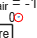


% plot data
figure;
hold on; 
plot((0:t_max-1)*dt, T_hist)
plot(burst_time, burst_T, 'ro', 'MarkerSize', 5); % plot failure
xlabel('Time (s)');
ylabel('Temperature (C)');
xlim([0, 600]);


title('Temperature of Still Water Freezing  in Copper Pipe')
subtitle(['at T_{air} = ', num2str(T_air), '\circ C'])
legend('Water Temperature', 'Pipe Burst')

clear
clc
% System Properties
T_air = -15; % air temperature (C) 
T_in = 1.67; % water initial temperature (C)
T = T_in;
T_freeze = 0; % temperature for freezing (C)
T_nucleation = -5; % temperature for nucleation (C)

cp_water = 4186; % specific heat capacity water (J/kg*K)
cp_ice = 2100; % specific heat capacity ice (J/kg*K)
L_f = 334000; % latent heat of fusion (J/kg)

D = 0.00555; % m
r = D/2; % m
L = 0.2; % m
A = D*pi*L; % convection area (m^2)
V = pi*r^2*L; % volume of water (m^3)

rho = 1000; % density (kg/m^3)
m = rho*V; % mass (kg)

flow_rate = 1; % flow rate of pump (liter/min)
m_dot = flow_rate/60; % mass flow rate (kg/s)

dt = 1; % time step (s)
t_max = 60*60*2;

h = 15; % heat transfer coefficient (W/m^2*K)
t_wall = 0.00028; % pipe wall thickness (m)
sigma_fail = 4e7; % copper pipe failure stress (Pa)
K = 2.2e9; % bulk modulus of water (Pa)
latent_remaining = m*L_f; % J
frozen = 0;

phase = "liquid";
burst = false;
T_hist = zeros(1, t_max);

for i = 1:t_max
    if phase == "liquid" && T <= T_nucleation
        phase = "freezing";
    end


    if phase =="liquid"
        T = T-h*A/(m*cp_water)*(T-T_air)*dt;

    elseif phase == "freezing"
        Q = h*A*(T-T_air)*dt;
        dQ = min(Q, latent_remaining);
        T = -(exp(h*(-2*pi*r*L)/(m_dot*cp_water))*(T_air-T_hist(i-1))-T_air);

        latent_remaining = latent_remaining-dQ;
        frozen = 1-latent_remaining/(m*L_f);
        % pressure from expansion
        strain = 0.09*frozen;
        P = K*strain;
        sigma = P*r/t_wall;

        % check for pipe failure
        if sigma >= sigma_fail
            disp(['Burst at t = ', num2str(i*dt)])
            burst = true;
            burst_index = i;
            burst_time = i*dt;
            burst_T = T;
            break
        end

        if latent_remaining <= 0
            phase = "solid";
            T=T_freeze;
        end

    elseif phase == "solid"
        break
    end

    T_hist(i) = T;
end

Burst at t = 263


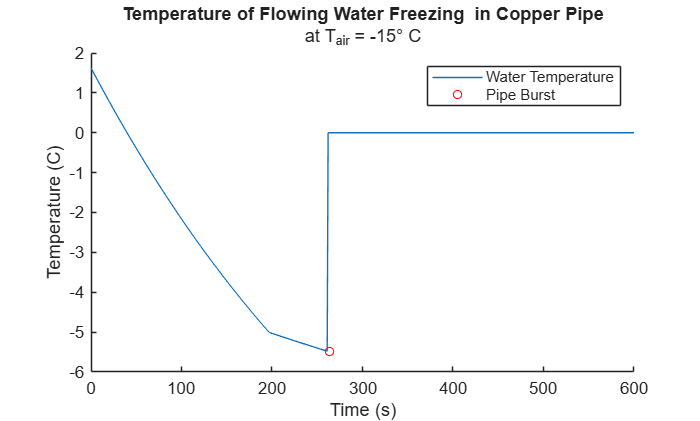



figure;
hold on; 
plot((0:t_max-1)*dt, T_hist)
plot(burst_time, burst_T, 'ro', 'MarkerSize', 5);
xlabel('Time (s)');
ylabel('Temperature (C)');
xlim([0, 600]);

title('Temperature of Flowing Water Freezing  in Copper Pipe')
subtitle(['at T_{air} = ', num2str(T_air), '\circ C'])
legend('Water Temperature', 'Pipe Burst')